# Setting Stuff Up!

clear all

syms theta1(t) theta2(t)
syms J1S J2S bS kS TcS Tc

eq1S = J1S*diff(theta1,2) + bS*(diff(theta1,1)-diff(theta2,1))+kS*(diff(theta1,0)-diff(theta2,0)) == TcS

$$eq1S(t) = \mathrm{bS}\,\left(\frac{\partial }{\partial t}\theta_{1}\left(t\right)-\frac{\partial }{\partial t}\theta_{2}\left(t\right)\right)+\mathrm{kS}\,\left(\theta_{1}\left(t\right)-\theta_{2}\left(t\right)\right)+\mathrm{J1S}\,\frac{\partial^{2}}{\partial t^{2}}\theta_{1}\left(t\right)=\mathrm{TcS}$$


eq2S = J2S*diff(theta2,2) + bS*(diff(theta2,1)-diff(theta1,1))+kS*(diff(theta2,0)-diff(theta1,0)) == 0 

$$eq2S(t) = \mathrm{J2S}\,\frac{\partial^{2}}{\partial t^{2}}\theta_{2}\left(t\right)-\mathrm{kS}\,\left(\theta_{1}\left(t\right)-\theta_{2}\left(t\right)\right)-\mathrm{bS}\,\left(\frac{\partial }{\partial t}\theta_{1}\left(t\right)-\frac{\partial }{\partial t}\theta_{2}\left(t\right)\right)=0$$

## Other Variables


J1 = 1 ;
J2 = 0.1;
b  = 1;
k  = 1;
Tc = 10;

t0 = 0; 
tFin = 3;



eq1 = J1*diff(theta1,2) + b*(diff(theta1,1)-diff(theta2,1))+k*(diff(theta1,0)-diff(theta2,0)) == Tc

$$eq1(t) = \theta_{1}\left(t\right)-\theta_{2}\left(t\right)+\frac{\partial }{\partial t}\theta_{1}\left(t\right)-\frac{\partial }{\partial t}\theta_{2}\left(t\right)+\frac{\partial^{2}}{\partial t^{2}}\theta_{1}\left(t\right)=10$$

eq2 = J2*diff(theta2,2) + b*(diff(theta2,1)-diff(theta1,1))+k*(diff(theta2,0)-diff(theta1,0)) == 0 

$$eq2(t) = \theta_{2}\left(t\right)-\theta_{1}\left(t\right)-\frac{\partial }{\partial t}\theta_{1}\left(t\right)+\frac{\partial }{\partial t}\theta_{2}\left(t\right)+\frac{\frac{\partial^{2}}{\partial t^{2}}\theta_{2}\left(t\right)}{10}=0$$

## Breakdown

[ODE_sym,Vars_sym] = odeToVectorField(eq2S, eq1S)

$$ODE\_sym = \left(\begin{array}{c} Y_{2}\\ \frac{\mathrm{TcS}-\mathrm{bS}\,Y_{2}+\mathrm{bS}\,Y_{4}-\mathrm{kS}\,Y_{1}+\mathrm{kS}\,Y_{3}}{\mathrm{J1S}}\\ Y_{4}\\ \frac{\mathrm{bS}\,Y_{2}-\mathrm{bS}\,Y_{4}+\mathrm{kS}\,Y_{1}-\mathrm{kS}\,Y_{3}}{\mathrm{J2S}} \end{array}\right)$$

$$Vars\_sym = \left(\begin{array}{c} \theta_{1}\\ {\mathrm{Dtheta}}_{1}\\ \theta_{2}\\ {\mathrm{Dtheta}}_{2} \end{array}\right)$$

[ODE,Vars] = odeToVectorField([eq2; eq1])

$$ODE = \left(\begin{array}{c} Y_{2}\\ 10\,Y_{3}-10\,Y_{2}-10\,Y_{1}+10\,Y_{4}\\ Y_{4}\\ Y_{1}+Y_{2}-Y_{3}-Y_{4}+10 \end{array}\right)$$

$$Vars = \left(\begin{array}{c} \theta_{2}\\ {\mathrm{Dtheta}}_{2}\\ \theta_{1}\\ {\mathrm{Dtheta}}_{1} \end{array}\right)$$

## Now we make temp function!

tmpMat = matlabFunction(ODE,'vars', {'t','Y'})

tmpMat = function_handle with value:
    @(t,Y)[Y(2);Y(1).*-1.0e+1-Y(2).*1.0e+1+Y(3).*1.0e+1+Y(4).*1.0e+1;Y(4);Y(1)+Y(2)-Y(3)-Y(4)+1.0e+1]


tmpMat(0,[2 4 4 2])

ans =      4
     0
     2
    10


## Setting up ODE45

initCon =25*[1 ; 2; 3 ; 4]; % The numbers map to Vars_sym's order

tSpan = [t0 tFin];  %time interval
sol = ode45( tmpMat,tSpan,initCon)

sol = struct with fields:
     solver: 'ode45'
    extdata: [1×1 struct]
          x: [0 0.0100 0.0603 0.1411 0.2331 0.3422 0.4720 0.6307 0.8312 1.0952 1.3952 1.6952 1.9952 2.2952 2.5952 2.8952 3]
          y: [4×17 double]
      stats: [1×1 struct]
      idata: [1×1 struct]


## Making Use of ODE45 Outputs

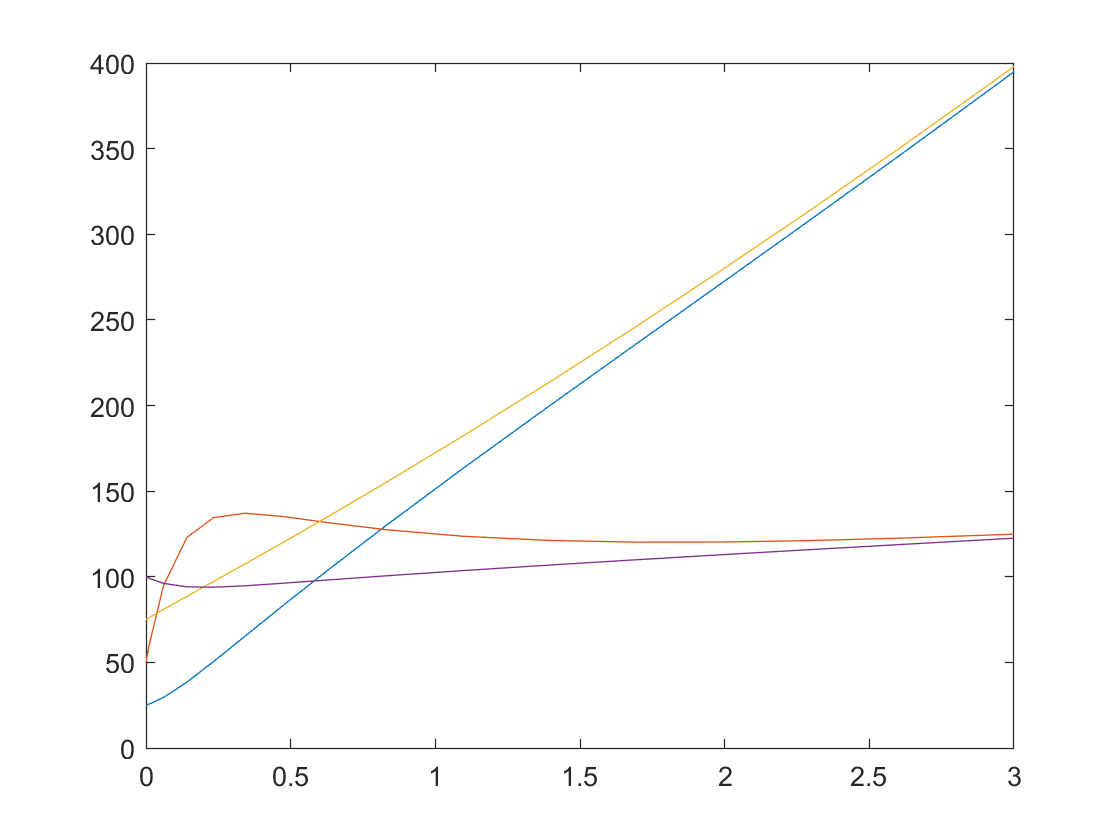

plot(sol.x, sol.y)

## Now we make temp function SYMBOLICALY!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!

tmpMatSym = matlabFunction(ODE_sym,'vars', {'t','Y','J1S','J2S','bS','kS','TcS'})

tmpMatSym = function_handle with value:
    @(t,Y,J1S,J2S,bS,kS,TcS)[Y(2);(TcS-bS.*Y(2)+bS.*Y(4)-kS.*Y(1)+kS.*Y(3))./J1S;Y(4);(bS.*Y(2)-bS.*Y(4)+kS.*Y(1)-kS.*Y(3))./J2S]


tmpMatSym(0,[2 4 4 2],1,2,3,4,5)

ans =      4
     7
     2
    -1


## Setting up ODE45 SYMBOLICALY!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!

initCon =25*[3; 4; 1 ; 2]; % The numbers map to Vars_sym's order

tSpan = [t0 tFin];  %time interval
solS = ode45(@(t,Y) tmpMatSym(t,Y,J1,J2,b,k,Tc),tSpan,initCon)

solS = struct with fields:
     solver: 'ode45'
    extdata: [1×1 struct]
          x: [0 0.0100 0.0603 0.1411 0.2331 0.3422 0.4720 0.6307 0.8312 1.0952 1.3952 1.6952 1.9952 2.2952 2.5952 2.8952 3]
          y: [4×17 double]
      stats: [1×1 struct]
      idata: [1×1 struct]


## Making Use of ODE45 Outputs

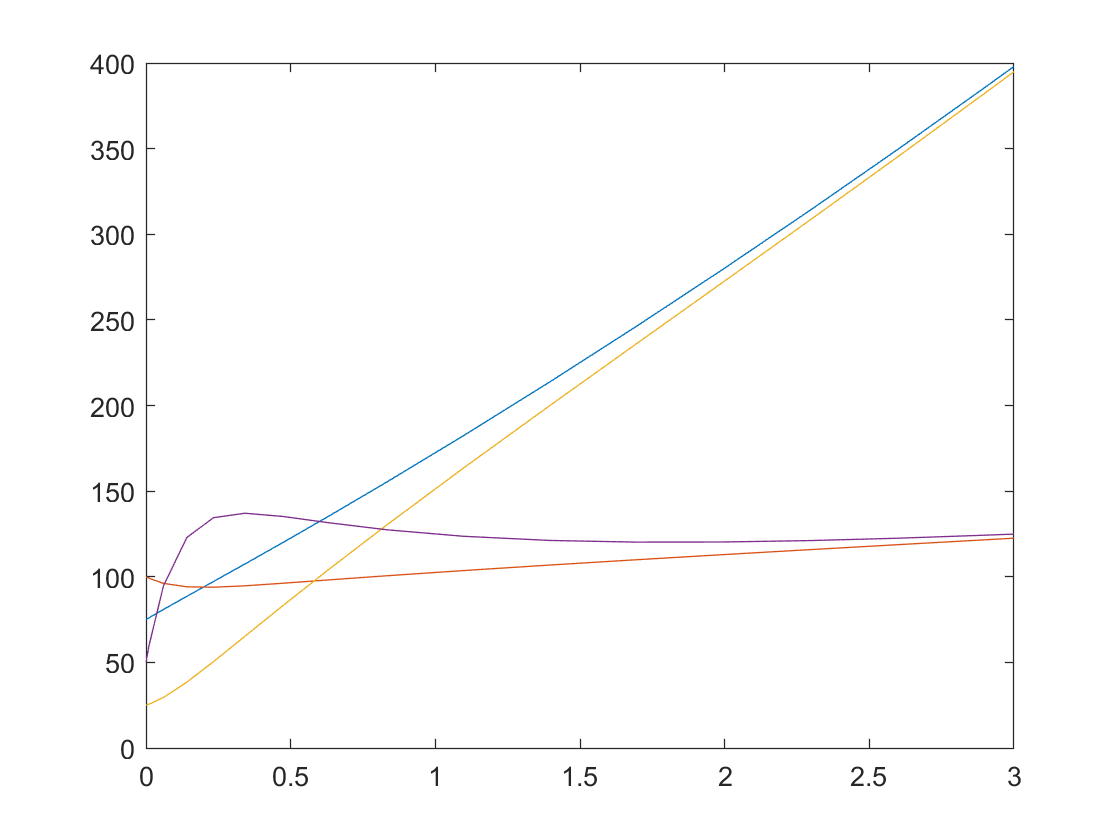

plot(solS.x, solS.y)